addpath('Utility_functions')
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

folder = '..\..\Data\25v_150g';

files = dir(folder);
files = files(3:end);
filesfmc = files([1 2 5 6 9 10 13 14 17 18 21 22 25 26]);
filesrayline = files([3 4 7 8 11 12 15 16 19 20 23 24 27 28]);

load("..\..\Data\USclutterdata\L22_14systeminfo.mat")
xs = ((-(Trans.numelements/2 -1):(Trans.numelements/2))-0.5)*Trans.spacingMm;
fs = Receive(1).decimSampleRate;
dt = 1/fs;
dz = dt*1.48/2;

% delays = [0.41 0.4 0.41 0.40 0.38 0.4 0.4; ...
%     0.37 0.39 0.40 0.39 0.39 0.36 0.41]
delay = 0.0;
% delays = [0.3472 0.3472 0 0 0 0];

irms = cell(14,1);
rms = cell(14,2);
tic;
delays = [0.37088 0.39456 0.41824 0.37088 0.41824 0.4064 0.39456 0.39456 0.38272 0.39456 0.37088 0.37088 0.3472 0.41824];
for i=1:14
    S = load(fullfile(folder,filesfmc(i).name));
    irm = RFtoRM(S.RcvData,S.Receive);
    irm = circshift(irm,-floor(delays(i)/dz),3);
    irms{i} = irm;
    rm = FMCtoFocused_frequency(irm,1.48,Receive,Trans,8,6,'a_shrink','boxcar');
    % rm = FMCtoFocused_time(irm,1.48,Receive,Trans,8,6,'a_shrink','boxcar');
    rms{i,1} = rm;
end

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

nelems = 13

% delays = [0 0 0 0 0 0 0 0];

for i=1:14
    S = load(fullfile(folder,filesrayline(i).name));
    rm = RFtoRM(S.RcvData,S.Receive);
    rm = circshift(rm,-floor(delays(i)/dz),3);
    rms{i,2} = rm;
end
t = toc;
t/60

ans = 1.8842


len = length(irms{4});
ts = dt*(0:(len-1));
zs = 1.48*ts/2;

% save irmandrms.mat irms rms len ts zs xs fs dt dz -v7.3

% load irmandrms.mat

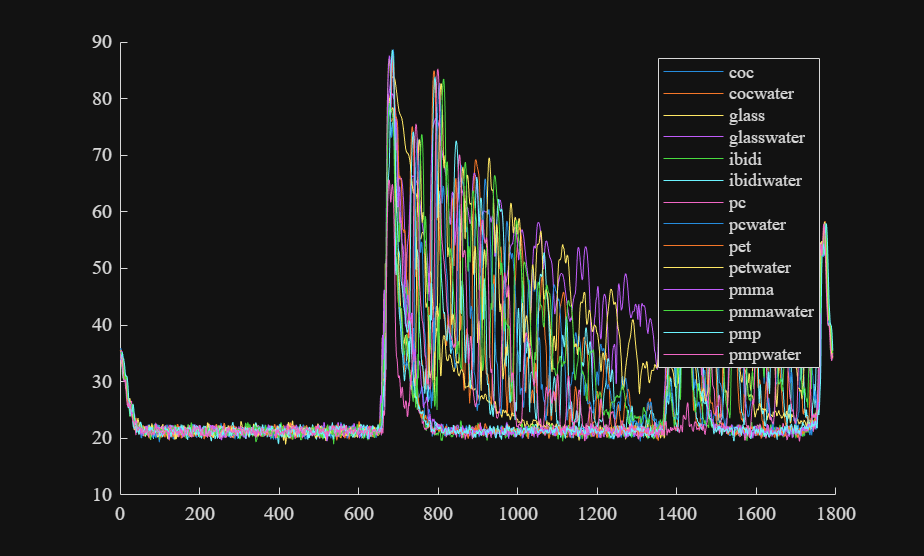

labels = {'coc','cocwater','glass','glasswater','ibidi','ibidiwater','pc','pcwater','pet','petwater','pmma','pmmawater','pmp','pmpwater'};

figure()
hold on
noise_level_fmc = 0;
% subset = [2 4 6 8];
subset = 1:14;
for i=subset
% figure()

% rm = irms{i};
rm = rms{i,1};
elems = 64 + (-40:40);
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(rm(j,j,1:len)))+1);
end
ave = ave / length(elems);
% plot(zs(1:len),ave)
plot(ave)
% title(labels{lab})
noise_level_fmc = noise_level_fmc + mean(ave(100:600))/14;
end
hold off

legend(labels(subset))

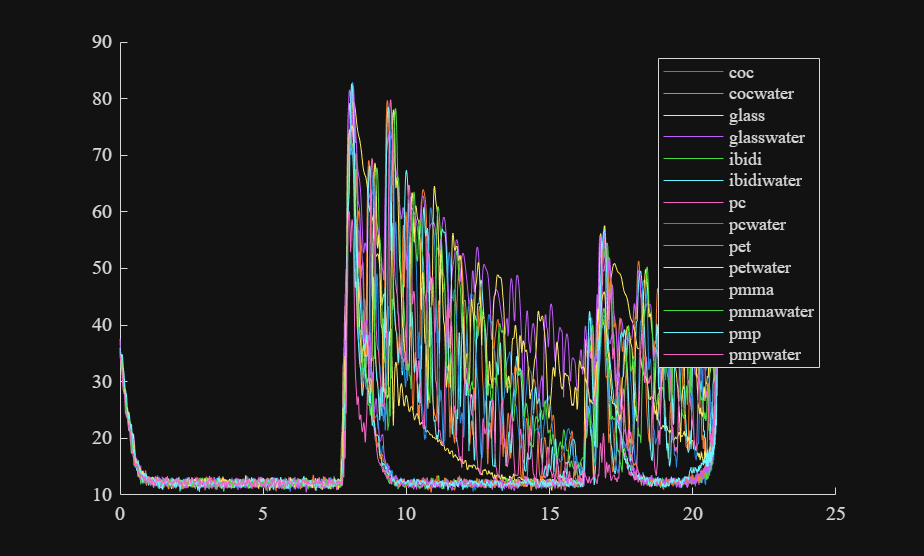

labels = {'coc','cocwater','glass','glasswater','ibidi','ibidiwater','pc','pcwater','pet','petwater','pmma','pmmawater','pmp','pmpwater'};

figure()
hold on
noise_level_rayline = 0;
% subset = [2 4 6 8];
subset = 1:14;
for i=subset
% figure()

% rm = irms{i};
rm = rms{i,2};
elems = 64 + (-40:40);
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(rm(j,j,1:len)))+1);
end
ave = ave / length(elems);
plot(zs(1:len),ave)
% plot(ave)
% title(labels{lab})
noise_level_rayline = noise_level_rayline + mean(ave(100:600))/14;
end
hold off

legend(labels(subset))

noise_levels = [noise_level_fmc noise_level_rayline]

noise_levels =    21.2378   12.1227


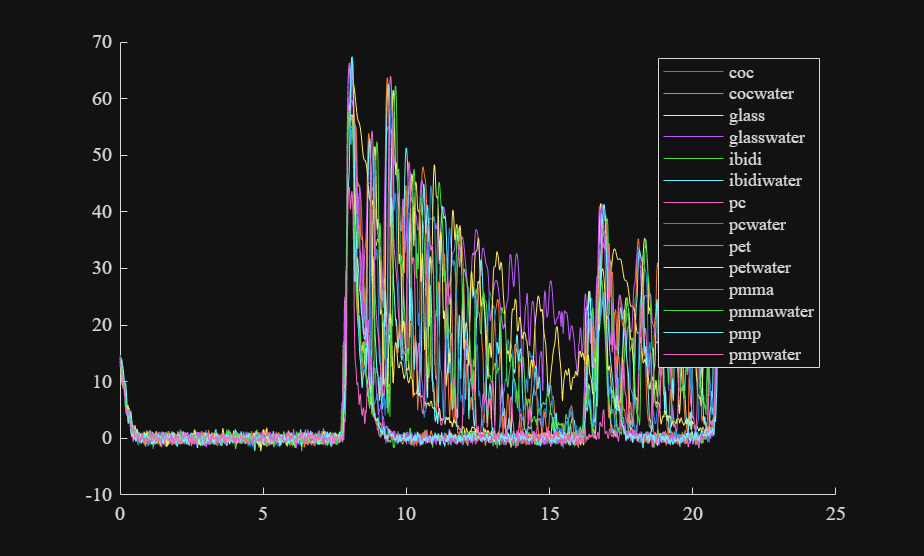

labels = {'coc','cocwater','glass','glasswater','ibidi','ibidiwater','pc','pcwater','pet','petwater','pmma','pmmawater','pmp','pmpwater'};

figure()
hold on
% noise_level_fmc = 0;
% subset = [2 4 6 8];
subset = 1:14;
for i=subset
% figure()

% rm = irms{i};
rm = rms{i,1};
elems = 64 + (-40:40);
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(rm(j,j,1:len)))+1);
end
ave = ave / length(elems);
plot(zs(1:len),ave - noise_levels(1))
% plot(ave)
% title(labels{lab})
% noise_level_fmc = noise_level_fmc + mean(ave(100:600))/14;
end
hold off

legend(labels(subset))

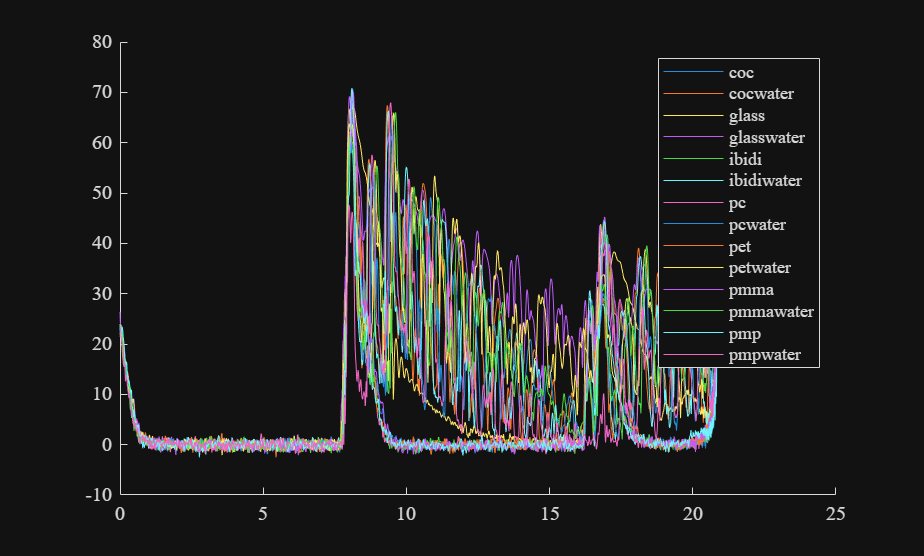

labels = {'coc','cocwater','glass','glasswater','ibidi','ibidiwater','pc','pcwater','pet','petwater','pmma','pmmawater','pmp','pmpwater'};

orderdry = [3 1 5 7 9 11 13];
orderwet = [4 2 6 8 10 12 14];

figure()
hold on
% noise_level_rayline = 0;
% subset = [2 4 6 8];
subset = 1:14;
for i=subset
% figure()

% rm = irms{i};
rm = rms{i,2};
elems = 64 + (-20:20);
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(rm(j,j,1:len)))+1);
end
ave = ave / length(elems);
plot(zs(1:len),ave - noise_levels(2))
% plot(ave)
% title(labels{lab})
% noise_level_rayline = noise_level_rayline + mean(ave(100:600))/14;
end
hold off

legend(labels(subset))

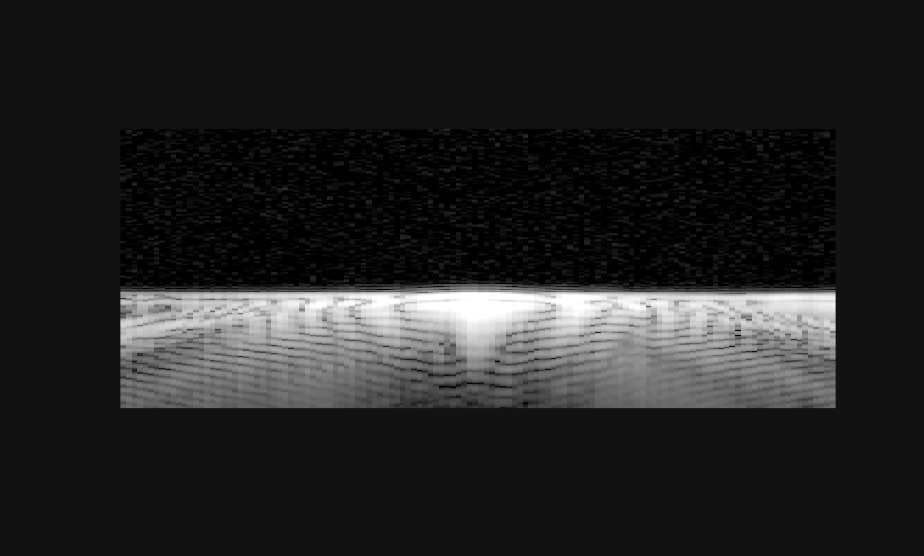

figure()
i = 3;
j = 2;
zsmask = zs < 10 & zs > 5;
% zsmask = zs < 8.2 & zs > 7.9;
imagesc(xs,zs(zsmask),20*log10(abs(squeeze(rms{i,j}(64,:,zsmask)))'+1),[noise_level_rayline,noise_level_rayline+60])
axis equal
axis off
colormap gray

for elem = (1+(1:31:128))

    figure()
    zsmask = zs < 10 & zs > 5;
    % zsmask = zs < 8.2 & zs > 7.9;
    imagesc(xs,zs(zsmask),20*log10(abs(squeeze(rms{i,j}(elem,:,zsmask)))'+1),[noise_level_rayline,noise_level_rayline+60])
    axis equal
    axis off
    colormap gray
end

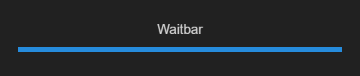

maxmodemeanrm = cell(14,2,3); %just rm data
% maxmodemeanrm = cell(7,4,3); % first two are dry and wet rayline, then dry and wet focused basis. 
wb = waitbar(0);
for i=1:14
    for j=1:2
        waitbar(((i-1)*2 +j)/28,wb);
        rm = rms{i,j};
        if j==1
            [levmed, levmax, levave, ~, ~] = off_axis_membrane_measure(xs,zs,7.9,8.2,rm,noise_levels(1));
        else
            [levmed, levmax, levave, ~, ~] = off_axis_membrane_measure(xs,zs,7.9,8.2,rm,noise_levels(2));
        end
        
        maxmodemeanrm{i,j,1} = levmax;
        maxmodemeanrm{i,j,2} = levmed;
        maxmodemeanrm{i,j,3} = levave;
    end

end

maxmodemeanrm_aves = zeros(size(maxmodemeanrm));
maxmodemeanrm_stds = zeros(size(maxmodemeanrm));
for i=1:14
    for j=1:2
        for k=1:3
            maxmodemeanrm_aves(i,j,k) = mean(maxmodemeanrm{i,j,k}(64 + (-40:40))); 
            maxmodemeanrm_stds(i,j,k) = std(maxmodemeanrm{i,j,k}(64 + (-40:40)));
            % maxmodemeanrm_stds(i,j,k) = 20*log10(std(10.^(maxmodemeanrm{i,j,k}(64 + (-40:40))/20)));
        end
    end
end

%compare SA clutter to Ray clutter
subset = 1:14;
sa_to_ray = zeros(14,2);

for i=subset
    [h,p] = ttest2(maxmodemeanrm{i,1,3}(64 + (-40:40)),maxmodemeanrm{i,2,3}(64 + (-40:40)));
    sa_to_ray(i,1) = h; sa_to_ray(i,2) = p;
end

dry_to_wet = zeros(7,2,2); %materials, then fmc/ray, then hypothesis testing results.
for i=1:7
    [h,p] = ttest2(maxmodemeanrm{2*i - 1,1,3}(64 + (-40:40)),maxmodemeanrm{2*i,1,3}(64 + (-40:40)));
    dry_to_wet(i,1,1) = h; dry_to_wet(i,1,2) = p;

    [h,p] = ttest2(maxmodemeanrm{2*i - 1,2,3}(64 + (-40:40)),maxmodemeanrm{2*i,2,3}(64 + (-40:40)));
    dry_to_wet(i,2,1) = h; dry_to_wet(i,2,2) = p;
end

disp(sa_to_ray)

    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000
    1.0000    0.0000



disp(squeeze(dry_to_wet(:,:,1)))

     1     1
     1     1
     1     1
     1     1
     1     1
     1     1
     1     1



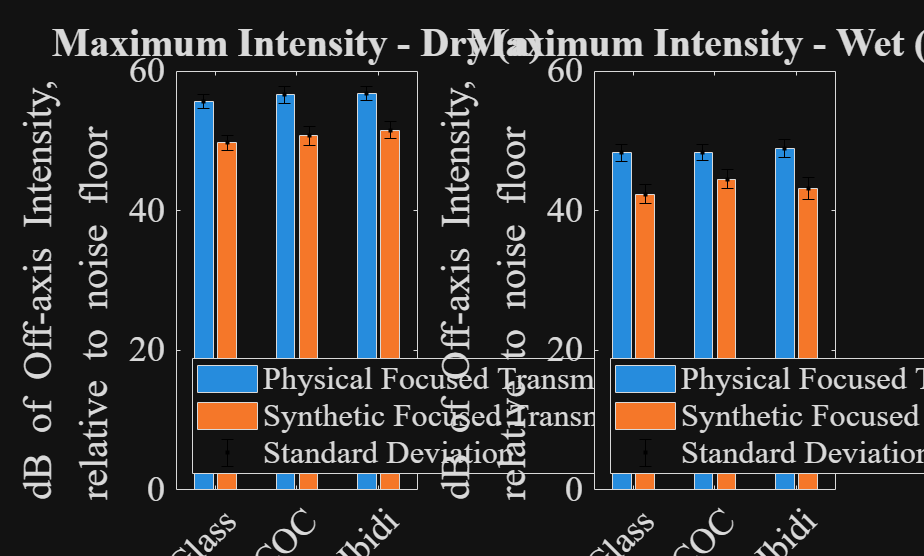

% orderdry = [3 1 5 13];
% orderwet = [4 2 6 14];

orderdry = [7 9 11];
orderwet = [8 10 12];
% orderdry = [3 1 5 7 9 11 13];
% orderwet = [4 2 6 8 10 12 14];
figure()
tiledlayout(1,2);
nexttile;

focused_dry_max = fliplr(squeeze(maxmodemeanrm_aves(orderdry,:,1)));
focused_wet_max = fliplr(squeeze(maxmodemeanrm_aves(orderwet,:,1)));

focused_dry_max_std = reshape(fliplr(squeeze(maxmodemeanrm_stds(orderdry,:,1)))',length(orderdry)*2,1);
focused_wet_max_std = reshape(fliplr(squeeze(maxmodemeanrm_stds(orderwet,:,1)))',length(orderdry)*2,1);
xsstds = reshape(repmat(1:length(orderdry),2,1) + [-0.15 0.15]',length(orderdry)*2,1);



fontsizessss = 18;


bar(focused_dry_max)

ylabel('dB of Off-axis Intensity, \newlinerelative to noise floor');
labelplot = {'Glass','COC','Ibidi','PC','PET','PMMA','PMP'};
xticklabels(labelplot);
ax = gca;
ax.FontSize = fontsizessss; 
title('Maximum Intensity - Dry (a)')
% ylim([-30,6])

hold on

stds_plot = reshape(focused_dry_max_std',length(orderdry)*2,1);

errorbar(xsstds,reshape(focused_dry_max',length(orderdry)*2,1),-stds_plot,stds_plot,'k.')

hold off
legend({'Physical Focused Transmission','Synthetic Focused Transmission','Standard Deviation'},"Location","southwest");
nexttile;
bar(focused_wet_max)

ylabel('dB of Off-axis Intensity, \newlinerelative to noise floor');
labelplot = {'Glass','COC','Ibidi','PC','PET','PMMA','PMP'};
xticklabels(labelplot);
ax = gca;
ax.FontSize = fontsizessss; 
title('Maximum Intensity - Wet (b)')
% ylim([-30,6])

hold on
stds_plot = reshape(focused_wet_max_std',length(orderdry)*2,1);

errorbar(xsstds,reshape(focused_wet_max',length(orderdry)*2,1),-stds_plot,stds_plot,'k.')

hold off
legend({'Physical Focused Transmission','Synthetic Focused Transmission','Standard Deviation'},"Location","southwest");

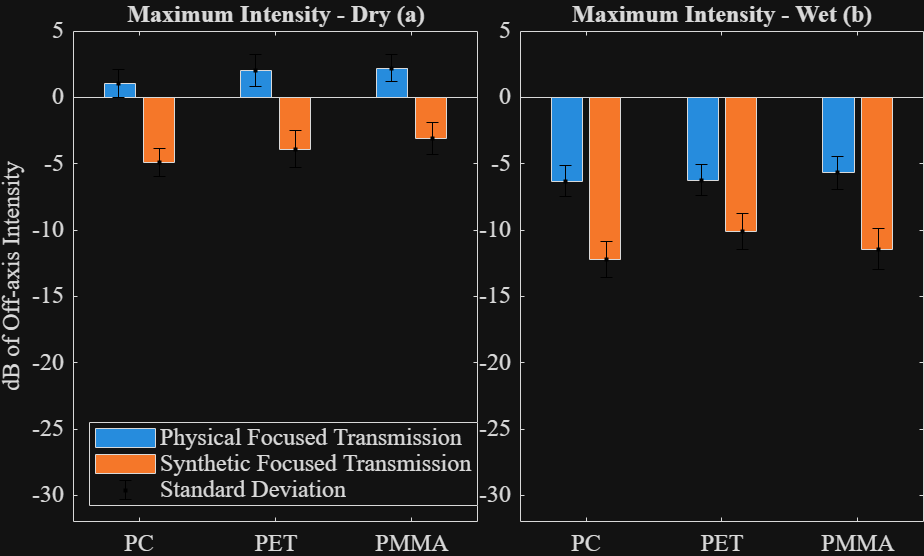

figure()
tiledlayout(1,2,'TileSpacing','tight','Padding','tight');
nexttile;

focused_dry_max = fliplr(squeeze(maxmodemeanrm_aves(orderdry,:,1)));
focused_wet_max = fliplr(squeeze(maxmodemeanrm_aves(orderwet,:,1)));

focused_dry_max_std = reshape(fliplr(squeeze(maxmodemeanrm_stds(orderdry,:,1)))',length(orderdry)*2,1);
focused_wet_max_std = reshape(fliplr(squeeze(maxmodemeanrm_stds(orderwet,:,1)))',length(orderdry)*2,1);
xsstds = reshape(repmat(1:length(orderdry),2,1) + [-0.15 0.15]',length(orderdry)*2,1);



fontsizessss = 18;


bar(focused_dry_max - maxmodemeanrm_aves(3,2,1))

ylabel('dB of Off-axis Intensity');
% labelplot = {'Glass','COC','Ibidi','PC','PET','PMMA','PMP'};
labelplot = {'COC','Glass','Ibidi','PC','PET','PMMA','PMP'};
xticklabels(labelplot(orderwet/2));
ax = gca;
ax.FontSize = fontsizessss; 
title('Maximum Intensity - Dry (a)')
ylim([-32 5])

hold on

stds_plot = reshape(focused_dry_max_std',length(orderdry)*2,1);

errorbar(xsstds,reshape(focused_dry_max',length(orderdry)*2,1)- maxmodemeanrm_aves(3,2,1),-stds_plot,stds_plot,'k.')

hold off
legend({'Physical Focused Transmission','Synthetic Focused Transmission','Standard Deviation'},"Location","southwest");
nexttile;
bar(focused_wet_max- maxmodemeanrm_aves(3,2,1))

% ylabel('dB of Off-axis Intensity');
labelplot = {'COC','Glass','Ibidi','PC','PET','PMMA','PMP'};
xticklabels(labelplot(orderwet/2));
ax = gca;
ax.FontSize = fontsizessss; 
title('Maximum Intensity - Wet (b)')
ylim([-32 5])

hold on
stds_plot = reshape(focused_wet_max_std',length(orderdry)*2,1);

errorbar(xsstds,reshape(focused_wet_max'- maxmodemeanrm_aves(3,2,1),length(orderdry)*2,1),-stds_plot,stds_plot,'k.')

hold off
% legend({'Physical Focused Transmission','Synthetic Focused Transmission','Standard Deviation'},"Location","southwest");
fontsize(12,'points')

rfnums = [1 1.4 2 3 4 5 6];%1:6;
% rfnums = [12]
beamformed = cell(14,2,length(rfnums));      % material; rayline dry, rayline wet, safb dry, safb wet; rfnums
wb = waitbar(0);
counter = 0;
total = 14*2*7;
for i=1:14
    for j=1:2
        % waitbar(((i-1)*2 + j) / 28,wb)
        
        rm = rms{i,j};
        
        for k=1:length(rfnums)
            counter = counter + 1;
            waitbar(counter/total,wb)
            [das_data,~,~] = das(rm,0,1.48,Trans,Receive,8,rfnums(k),'a_shrink','boxcar');
            beamformed{i,j,k} = das_data;
        end
    end
end

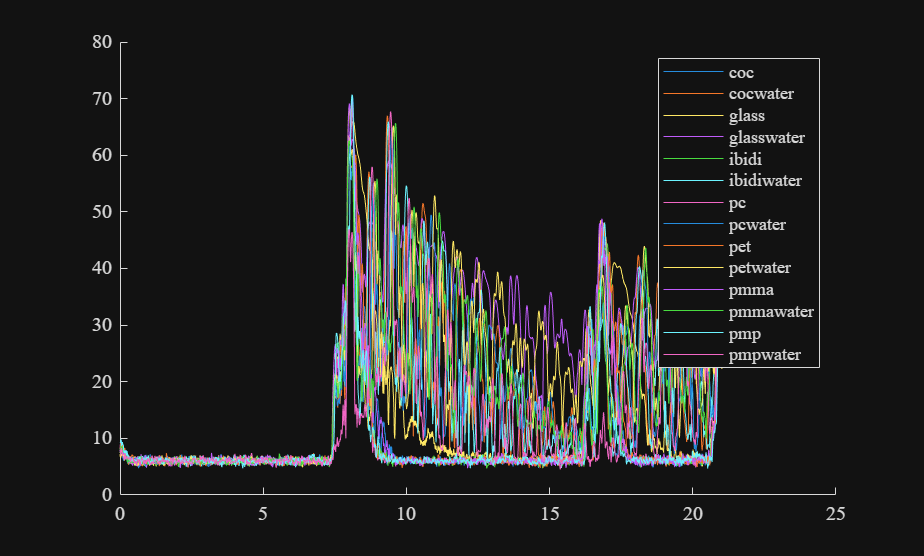

labels = {'coc','cocwater','glass','glasswater','ibidi','ibidiwater','pc','pcwater','pet','petwater','pmma','pmmawater','pmp','pmpwater'}; 
figure()
hold on
lab = 1;
subset = 1:14;
for i=subset
% figure()
% das_data = beamformed{i,2};

das_data = beamformed{i,1,1};

elems = 64 + (-20:20);
% elems = 64;
ave = zeros(len,1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(das_data(j,1:len)))'+1);
end
ave = ave / length(elems);
plot(zs(1:len),ave)

% title(labels{lab})
lab=lab+1;
end
hold off

legend(labels(subset))

% figure()
% hold on
noise_levels_bmode = zeros(2,length(rfnums));
subset = 1:14;
for k=1:length(rfnums)
    for l=1:2
        
        for i=subset
        
            das_data = beamformed{i,l,k};
            
            elems = 64 + (-20:20);
            % elems = 64;
            ave = zeros(len,1);
            for j=elems
                ave = ave + 20*log10(abs(squeeze(das_data(j,1:len)))'+1);
            end
            ave = ave / length(elems);
            noise_levels_bmode(l,k) = noise_levels_bmode(l,k) + mean(ave(100:550))/14;
        end

    end

end

noise_levels_bmode

noise_levels_bmode =     6.0295    6.6857    7.5280    8.6017    9.3102    9.9190   10.3045
    2.1638    2.4805    2.9085    3.4733    3.8545    4.2159    4.4445


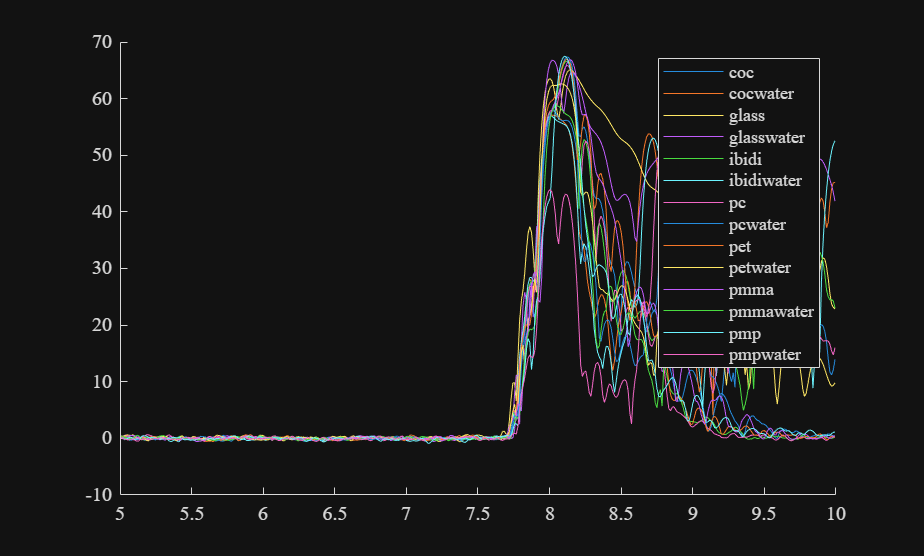

figure()
hold on
zmask = zs > 5 & zs < 10;
subset = 1:14;
k=3; %fnumber for reception beamforming
l=2; %1-> fmc, 2-> rayline
for i=subset

das_data = beamformed{i,l,k};

elems = 64 + (-20:20);
% elems = 64;
ave = zeros(sum(zmask),1);
for j=elems
    ave = ave + 20*log10(abs(squeeze(das_data(j,zmask)))'+1);
end
ave = ave / length(elems);
% plot(zs(1:len),ave)
plot(zs(zmask),ave - noise_levels_bmode(l,k))
% title(labels{lab})
end
hold off

legend(labels(subset))

zsmaskint = zs >7.4 & zs <7.85;
clutterdb = zeros(14,2,length(rfnums),41);
signaldb = zeros(14,2,length(rfnums),41);


for k=1:length(rfnums); %fnumber for reception beamforming
for l=1:2; %1-> fmc, 2-> rayline
subset = 1:14;
for i=subset

das_data = beamformed{i,l,k};

elems = 64 + (-20:20);
% elems = 64;

for j=elems
    clutterdb(i,l,k,j-43) = mean(20*log10(abs(squeeze(das_data(j,zsmaskint)))'+1) - noise_levels_bmode(l,k));
    signaldb(i,l,k,j-43) = 20*log10(abs(squeeze(das_data(j, 677)))'+1) - noise_levels_bmode(l,k);
end

end
end
end
%first dim: material and dryness
%second dim: fmc or rayline
%third dim: receive fnum
%fourth dim: bmode average value in region

%check for every rfnumber, if the differences in clutter are statistically
%significant

difference_in_acq = zeros(7,4,4,length(rfnums),2); %material, then cross between the 4 (redundant), rfnums, and stats results
difference_from_glass_dry_ray = zeros(7,4,length(rfnums),2);
% the 4 are 'dry fmc','dry rayline','wet fmc','wet rayline'
for i=1:7
    for j=1:4
        for k=1:4
            for l=1:length(rfnums)
                if j==1 || j==2
                    i1 = 2*i -1;
                else
                    i1 = 2*i;
                end

                if k==1 || k==2
                    i2 = 2*i -1;
                else
                    i2 = 2*i;
                end


                [h,p] = ttest2(squeeze(clutterdb(i1,2-mod(j,2),l,:)),squeeze(clutterdb(i2,2-mod(k,2),l,:)));
                difference_in_acq(i,j,k,l,1) = h;
                difference_in_acq(i,j,k,l,2) = p;
                if j==1
                    [h,p] = ttest2(squeeze(clutterdb(3,2,l,:)),squeeze(clutterdb(i2,2-mod(k,2),l,:)));
                    difference_from_glass_dry_ray(i,k,l,1) = h;
                    difference_from_glass_dry_ray(i,k,l,2) = p;
                end


            end
        end
    end
end


i=7;
l=3;
disp([labels{2*i-1} ' rfnum = ' num2str(rfnums(l))])

pmp rfnum = 2


disp([squeeze(difference_in_acq(i,:,:,l,1)) squeeze(difference_in_acq(i,:,:,l,2))])

         0    1.0000         0         0    1.0000    0.0034    0.9487    0.7389
    1.0000         0    1.0000    1.0000    0.0034    1.0000    0.0037    0.0000
         0    1.0000         0         0    0.9487    0.0037    1.0000    0.6770
         0    1.0000         0         0    0.7389    0.0000    0.6770    1.0000



%', the 4 are dry fmc, dry rayline, wet fmc, wet rayline'

i=2;
l=3;
disp([labels{2*i-1} ' rfnum = ' num2str(rfnums(l))])

glass rfnum = 2


disp([squeeze(difference_from_glass_dry_ray(i,:,l,1)) ;squeeze(difference_from_glass_dry_ray(i,:,l,2))])

         0         0    1.0000    1.0000
    0.0766    1.0000    0.0280    0.0000



%', the 4 are dry fmc, dry rayline, wet fmc, wet rayline'

clutterdb_ave = mean(clutterdb,4);
clutterdb_std = std(clutterdb,0,4);
signaldb_ave = mean(signaldb,4);

clutterdb_norm = zeros(14,2,length(rfnums),41);

for k=1:length(rfnums); %fnumber for reception beamforming
for l=1:2; %1-> fmc, 2-> rayline
subset = 1:14;
for i=subset

das_data = beamformed{i,l,k};

elems = 64 + (-20:20);
% elems = 64;

for j=elems
    clutterdb_norm(i,l,k,j-43) = mean((signaldb_ave(i,1,k)/signaldb_ave(i,l,k))*(20*log10(abs(squeeze(das_data(j,zsmaskint)))'+1) - noise_levels_bmode(l,k)));
    % signaldb(i,l,k,j-43) = 20*log10(abs(squeeze(das_data(j, 677)))'+1) - noise_levels_bmode(l,k);
end

end
end
end
clutterdb_norm_ave = mean(clutterdb_norm,4);
clutterdb_norm_std = std(clutterdb_norm,0,4);

%check for every rfnumber, if the differences in clutter are statistically
%significant

difference_in_acq_norm = zeros(7,4,4,length(rfnums),2); %material, then cross between the 4 (redundant), rfnums, and stats results
% the 4 are 'dry fmc','dry rayline','wet fmc','wet rayline'
for i=1:7
    for j=1:4
        for k=1:4
            for l=1:length(rfnums)
                if j==1 || j==2
                    i1 = 2*i -1;
                else
                    i1 = 2*i;
                end

                if k==1 || k==2
                    i2 = 2*i -1;
                else
                    i2 = 2*i;
                end


                [h,p] = ttest2(squeeze(clutterdb_norm(i1,2-mod(j,2),l,:)),squeeze(clutterdb_norm(i2,2-mod(k,2),l,:)));
                difference_in_acq_norm(i,j,k,l,1) = h;
                difference_in_acq_norm(i,j,k,l,2) = p;


            end
        end
    end
end


i=3;
l=3;
disp([labels{2*i-1} ' rfnum = ' num2str(rfnums(l))])

ibidi rfnum = 2


% disp(squeeze(difference_in_acq_norm(i,:,:,l,1) - difference_in_acq(i,:,:,l,1)))
disp(squeeze(difference_in_acq(i,:,:,l,1)))

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



%', the 4 are dry fmc, dry rayline, wet fmc, wet rayline'

figure()
letters = {'(a)','(b)','(c)','(d)'}

letters = 1×4 cell array
    {'(a)'}    {'(b)'}    {'(c)'}    {'(d)'}


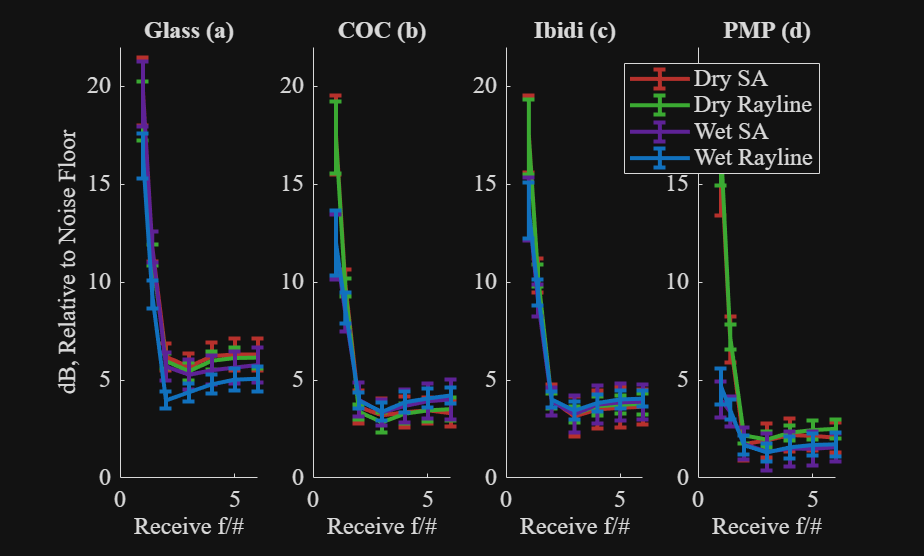

tiledlayout(1,4);
titles ={'COC','Glass','Ibidi','PC','PET','PMMA','PMP'};
counter = 1;
for i=[2 1 3 7]
    nexttile;
    hold on
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +1,1,:)),squeeze(clutterdb_std((i-1)*2 +1,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +1,2,:)),squeeze(clutterdb_std((i-1)*2 +1,2,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +2,1,:)),squeeze(clutterdb_std((i-1)*2 +2,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +2,2,:)),squeeze(clutterdb_std((i-1)*2 +2,2,:)),'LineWidth',2)
    colororder('dye')
    if i==2
        
        ylabel('dB, Relative to Noise Floor')
    elseif i==7
        legend({'Dry SA','Dry Rayline','Wet SA','Wet Rayline'})
    end
    title([titles{i} ' ' letters{counter}])
    counter = counter + 1;
    ylim([0 22])
    xlabel('Receive f/#')
    hold off
end
fontsize(12,'points')

labels

labels = 1×14 cell array
    {'coc'}    {'cocwater'}    {'glass'}    {'glasswater'}    {'ibidi'}    {'ibidiwater'}    {'pc'}    {'pcwater'}    {'pet'}    {'petwater'}    {'pmma'}    {'pmmawater'}    {'pmp'}    {'pmpwater'}


disp([(squeeze(clutterdb_ave(:,:,3)) - squeeze(clutterdb_ave(3,2,3))) squeeze(clutterdb_std(:,:,3))])

   -2.3436   -2.5850    0.8572    0.3743
   -1.9766   -2.0228    0.8646    0.4139
    0.2191         0    0.6830    0.3814
   -0.2765   -2.0082    0.6932    0.4355
   -1.9885   -2.0492    0.8028    0.3922
   -2.0699   -1.9642    0.7083    0.3951
   -1.8262   -2.2641    0.8769    0.5345
   -2.6675   -3.1952    1.0699    0.6902
   -2.3880   -2.3836    1.2932    1.1083
   -2.2881   -2.7175    1.5046    0.5453
   -0.7717   -3.6897    0.8617    0.3688
   -2.1723   -3.7612    1.4795    0.8496
   -4.2397   -3.7972    0.8360    0.4231
   -4.2279   -4.2904    0.8204    0.4935



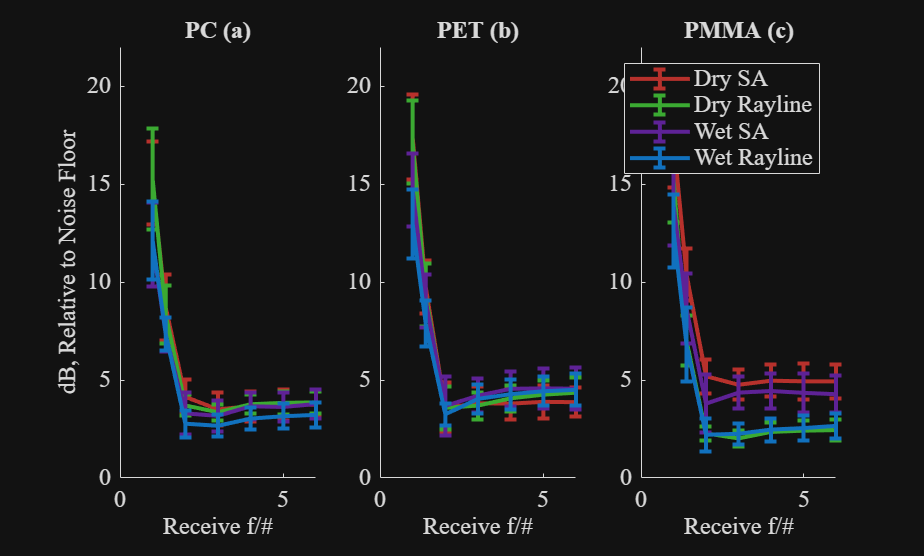

figure()

tiledlayout(1,3);
titles ={'COC','Glass','Ibidi','PC','PET','PMMA','PMP'};
counter = 1;
for i=[4 5 6]
    nexttile;
    hold on
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +1,1,:)),squeeze(clutterdb_std((i-1)*2 +1,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +1,2,:)),squeeze(clutterdb_std((i-1)*2 +1,2,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +2,1,:)),squeeze(clutterdb_std((i-1)*2 +2,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_ave((i-1)*2 +2,2,:)),squeeze(clutterdb_std((i-1)*2 +2,2,:)),'LineWidth',2)
    colororder('dye')
    if i==4
        
        ylabel('dB, Relative to Noise Floor')
    elseif i==6
        legend({'Dry SA','Dry Rayline','Wet SA','Wet Rayline'})
    end
    title([titles{i} ' ' letters{counter}])
    counter = counter + 1;
    ylim([0 22])
    hold off
    xlabel('Receive f/#')
end
fontsize(12,'points')

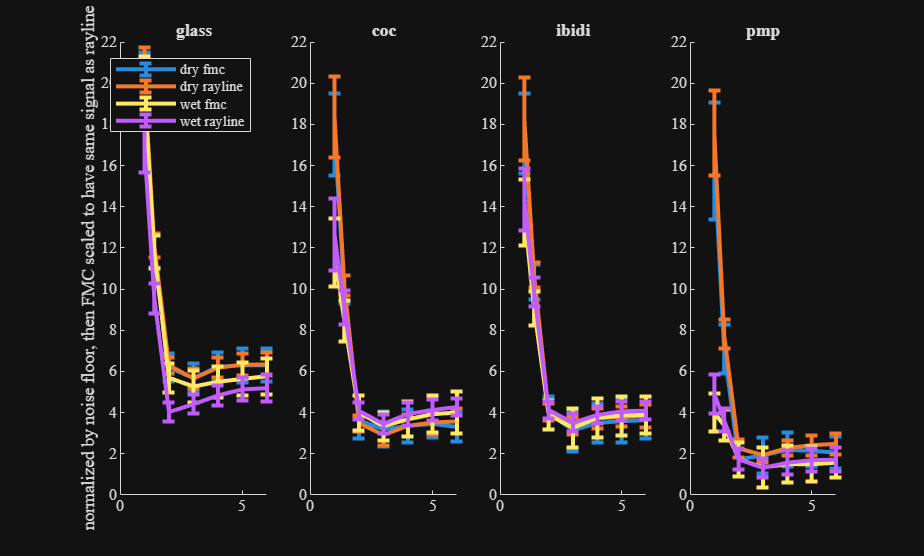

figure()

tiledlayout(1,4);
titles ={'coc','glass','ibidi','pc','pet','pmma','pmp'};
for i=[2 1 3 7]
    nexttile;
    hold on
    errorbar(rfnums,squeeze(clutterdb_norm_ave((i-1)*2 +1,1,:)),squeeze(clutterdb_norm_std((i-1)*2 +1,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_norm_ave((i-1)*2 +1,2,:)),squeeze(clutterdb_norm_std((i-1)*2 +1,2,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_norm_ave((i-1)*2 +2,1,:)),squeeze(clutterdb_norm_std((i-1)*2 +2,1,:)),'LineWidth',2)
    errorbar(rfnums,squeeze(clutterdb_norm_ave((i-1)*2 +2,2,:)),squeeze(clutterdb_norm_std((i-1)*2 +2,2,:)),'LineWidth',2)

    if i==2
        legend({'dry fmc','dry rayline','wet fmc','wet rayline'})
        ylabel('normalized by noise floor, then FMC scaled to have same signal as rayline')
    end
    title(titles(i))
    ylim([0 22])
    hold off
end

signaldb_diff = squeeze(signaldb_ave(:,2,:) - signaldb_ave(:,1,:))

signaldb_diff =    -2.9111   -2.4388   -1.8349   -1.5638   -1.3951   -1.2544   -1.1183
   -2.8185   -2.4592   -1.9486   -1.3595   -1.0861   -0.9870   -0.8940
   -4.3046   -3.8417   -3.4865   -2.5666   -2.3111   -2.3162   -2.2684
   -1.4820   -1.3640   -1.1924   -0.4772   -0.7948   -1.5336   -1.7669
   -2.5213   -1.9414   -1.5378   -1.3858   -1.1369   -0.9909   -0.8679
   -2.6321   -2.2341   -1.7916   -1.2557   -0.9383   -0.8306   -0.7374
   -2.8580   -2.3227   -2.0255   -1.5587   -1.2533   -1.1087   -0.9814
   -3.4461   -3.0586   -2.6533   -2.0061   -1.6458   -1.4514   -1.2928
   -3.4794   -3.1133   -2.5027   -1.8966   -1.6778   -1.5497   -1.4364
   -0.2799   -0.0032    0.2962    0.8945    0.3688   -0.0597   -0.1793


labels

labels = 1×14 cell array
    {'coc'}    {'cocwater'}    {'glass'}    {'glasswater'}    {'ibidi'}    {'ibidiwater'}    {'pc'}    {'pcwater'}    {'pet'}    {'petwater'}    {'pmma'}    {'pmmawater'}    {'pmp'}    {'pmpwater'}


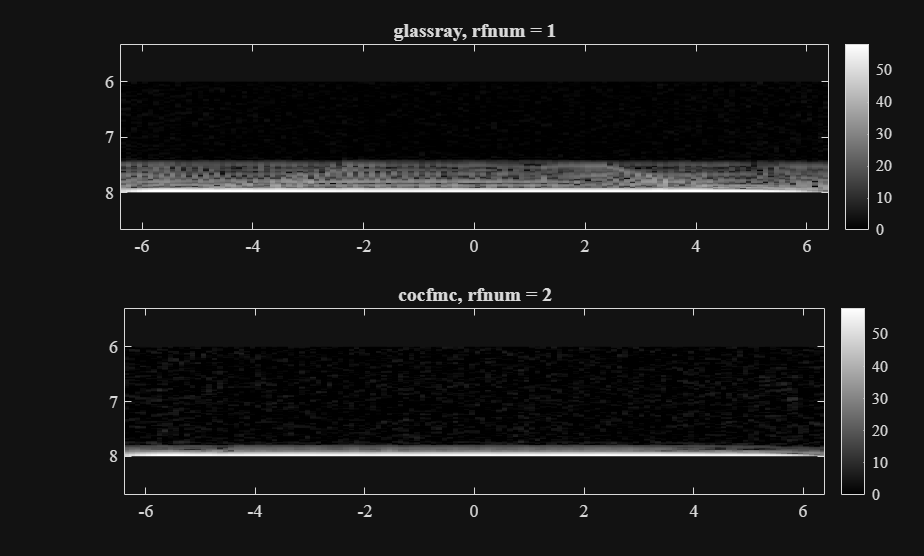

figure()
tiledlayout(2,1)
pairs = [3 2 1; 1 1 3];
maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
for p=1:2
    nexttile;
    i = pairs(p,1); j = pairs(p,2); k = pairs(p,3);

    % % maskxs = xs > (2-1) & xs < (2+1); 
    % i = 3; %file
    % j = 2;%fmc or ray
    % k = 3;%rfnum
    
    imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)' - noise_levels_bmode(j,k),[0 signaldb_ave(3,2,1)])
    colormap gray
    axis equal
    colorbar
    if j==1
        title([labels{i} 'fmc, rfnum = ' num2str(rfnums(k))])
    else
        title([labels{i} 'ray, rfnum = ' num2str(rfnums(k))])
    end
end

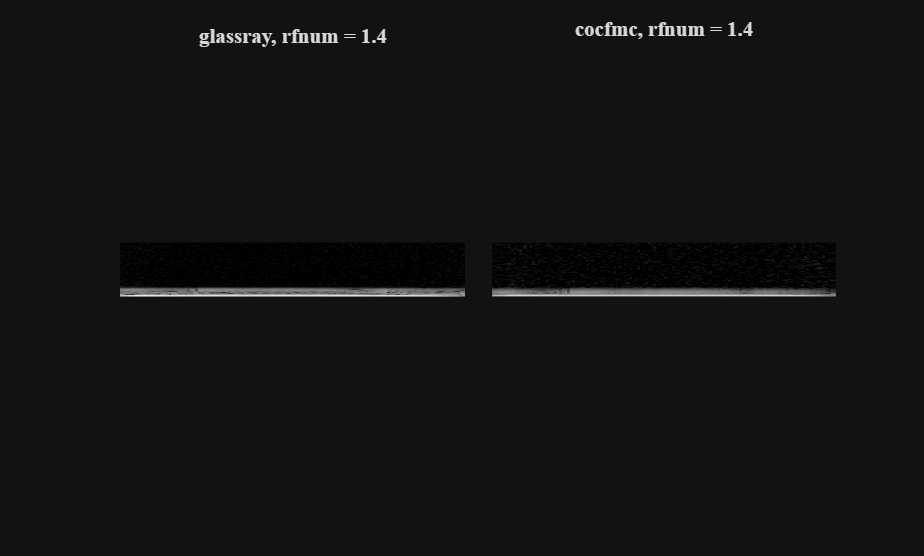

figure()
tiledlayout(1,2,'TileSpacing','tight')
pairs = [3 2 2; 1 1 2];
maskzs = zs > 6 & zs < 8;
maskxs = xs > (-100) & xs < (100);
for p=1:2
    nexttile;
    i = pairs(p,1); j = pairs(p,2); k = pairs(p,3);

    % % maskxs = xs > (2-1) & xs < (2+1); 
    % i = 3; %file
    % j = 2;%fmc or ray
    % k = 3;%rfnum
    
    imagesc(xs(maskxs),zs(maskzs),20*log10(abs(squeeze(beamformed{i,j,k}(maskxs,maskzs)))+1)' - noise_levels_bmode(j,k),[0 signaldb_ave(3,1,2)])
    colormap gray
    axis equal
    % colorbar
    axis off
    if j==1
        title([labels{i} 'fmc, rfnum = ' num2str(rfnums(k))])
    else
        title([labels{i} 'ray, rfnum = ' num2str(rfnums(k))])
    end
end

function [levelsmedian,levels_max,levels_ave,binss,binneds] = off_axis_membrane_measure(xs,zs,zmin,zmax,IRMorRM,noise_level) 
zmask = (zs > zmin) & (zs < zmax);
zmask = repmat(zmask',1,128);
levelsmedian = zeros(128,1);
levels_max =zeros(128,1);
levels_ave =zeros(128,1);
binss = cell(128,1);
binneds = cell(128,1);
for i=1:128
    x = xs(i);
    xmask = (xs > x+5) | (xs < x-5);
    xmask = repmat(xmask,length(zs),1); 
    glass_mask = zmask & xmask;
    bmode = 20*log10(squeeze(abs(IRMorRM(i,:,:))).'+1) - noise_level;% - max(max(20*log10(squeeze(abs(IRMorRM(i,:,:))).'+1)));
    data = bmode(glass_mask);
    step = 1;
    bins = floor(min(data)):step:ceil(max(data));
    lbin = bins - step/2;
    hbin = bins +step/2;
    binned = zeros(1, length(bins));
    for j=1:length(bins)
        binned(j) = sum((data>lbin(j)) & (data<hbin(j)));
    end
%     bar(bins,binned)
    level = bins(find(binned == max(binned),1,"last"));
    levels_max(i) = max(data);
    levels_ave(i) = 20*log10(mean(10.^(data/20)));
    levelsmedian(i) = level;
    binss{i} = bins;
    binneds{i} = binned;
end
% size(data)
end